# Sensing System - Performance Evaluation

## Initialize the Evaluation Script

clear;
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
%  file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
file_path = "4GHz.json";

config_path = david_path + file_path;

### Test Chirp Slopes

%initialize variables for different scenarios
chirp_cycle_period_us = 50;
%slopes_to_compute = 0.5:0.05:1.4; %for 20 MHz
slopes_to_compute = 100:10:200;
%for low slopes, need to go into
%Radar_Signal_processor/configure_low_pass_filter, and change to low
%stopband
frames_to_compute = 5;

%initialize variables to store results
num_test_cases = size(slopes_to_compute,2);
actual_slopes = zeros(1,num_test_cases);
estimated_slopes = zeros(1,num_test_cases);

%variable to store the error
errors = zeros(1,num_test_cases);

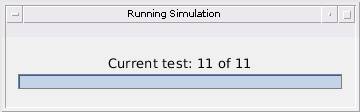

current_test_case = 1;
status = sprintf("Current test: %d of %d",1, num_test_cases);
                progress_bar = waitbar(0,status,"Name","Running Simulation");
for current_test_case = 1:num_test_cases

    status = sprintf("Current test: %d of %d",current_test_case, num_test_cases);
                        waitbar(current_test_case/num_test_cases,progress_bar,status);
    [actual_slope,estimated_slope,...
        actual_chirp_duration,estimated_chirp_duration,...
        actual_frame_duration, estimated_frame_duration] = ...
        compute_sensed_values(config_path,slopes_to_compute(current_test_case),chirp_cycle_period_us, frames_to_compute);
    %save values
    actual_slopes(current_test_case) = actual_slope;
    estimated_slopes(current_test_case) = estimated_slope;
    errors(current_test_case) = actual_slope - estimated_slope;
end

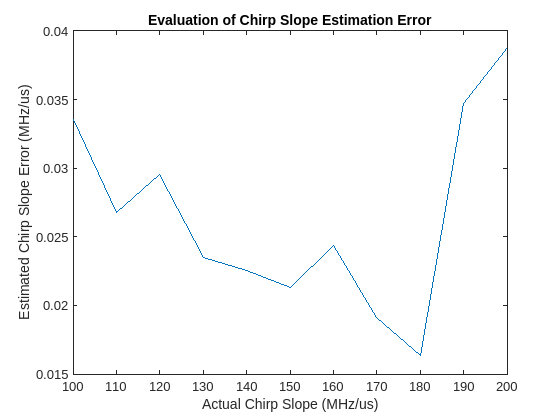

clf;
plot(actual_slopes,errors)
title("Evaluation of Chirp Slope Estimation Error")
xlabel("Actual Chirp Slope (MHz/us)")
ylabel("Estimated Chirp Slope Error (MHz/us)")

%ylim([-0.01,0.01])

### Test Chirp Period

%initialize variables for different scenarios

%20 MHz
% chirp_cycle_periods_us = 25:1:50;
% slope_MHz_us = 1.33;
%4 GHz
chirp_cycle_periods_us = 25:1:50;
slope_MHz_us = 200;


frames_to_compute = 5;

%initialize variables to store results
num_test_cases = size(chirp_cycle_periods_us,2);
actual_chirp_cycle_periods = zeros(1,num_test_cases);
estimated_chirp_cycle_periods = zeros(1,num_test_cases);

%variable to store the error
errors = zeros(1,num_test_cases);

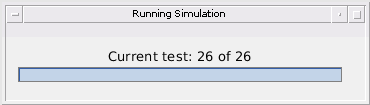

current_test_case = 1;
status = sprintf("Current test: %d of %d",1, num_test_cases);
                progress_bar = waitbar(0,status,"Name","Running Simulation");
for current_test_case = 1:num_test_cases

    status = sprintf("Current test: %d of %d",current_test_case, num_test_cases);
                        waitbar(current_test_case/num_test_cases,progress_bar,status);
    [actual_slope,estimated_slope,...
        actual_chirp_duration,estimated_chirp_duration,...
        actual_frame_duration, estimated_frame_duration] = ...
        compute_sensed_values(config_path,slope_MHz_us,chirp_cycle_periods_us(current_test_case), frames_to_compute);
    %save values
    actual_chirp_cycle_periods(current_test_case) = actual_chirp_duration;
    estimated_chirp_cycle_periods(current_test_case) = estimated_chirp_duration;
    errors(current_test_case) = actual_chirp_duration - estimated_chirp_duration;
end

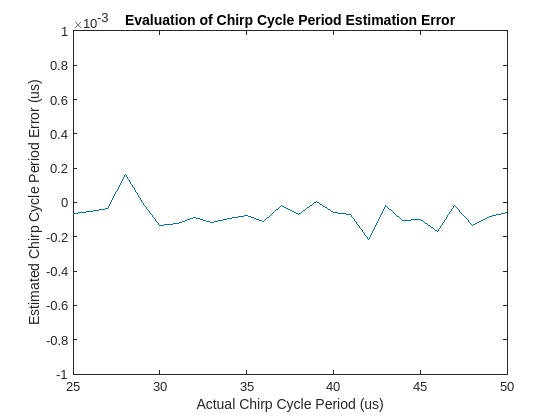

clf;
plot(actual_chirp_cycle_periods,errors)
title("Evaluation of Chirp Cycle Period Estimation Error")
xlabel("Actual Chirp Cycle Period (us)")
ylabel("Estimated Chirp Cycle Period Error (us)")
ylim([-0.001,0.001])